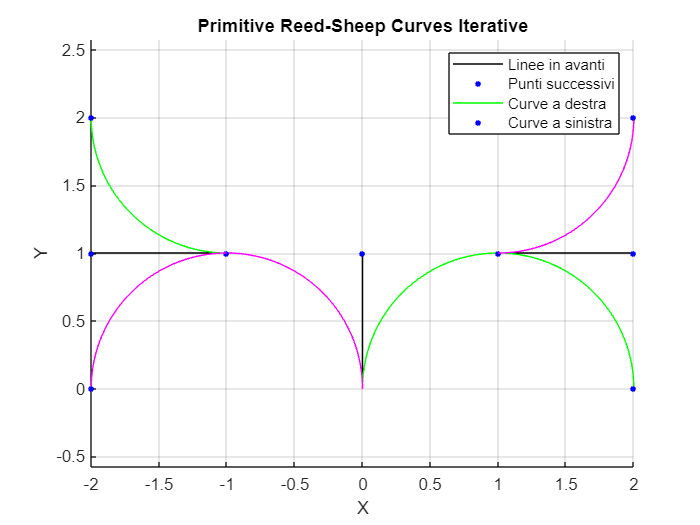

% Definizione dei parametri
lunghezza_passo = 1.0; % Lunghezza del passo in avanti
raggio_curva = 1.0; % Raggio di curvatura per le curve a destra e sinistra
num_iterazioni = 5; % Numero di iterazioni

% Punto iniziale (centro degli assi)
punto_iniziale = [0, 0];

% Inizializzazione del vettore per i punti
punti = zeros(((num_iterazioni + 1)^2), 2);
punti(1, :) = punto_iniziale;

punto_finale_destra = zeros(length(punti),2);
punto_finale_sinistra = zeros(length(punti),2);

% Contatore dei punti
contatore = 1;

% Calcolo dei punti successivi
for iter = 1:num_iterazioni
    % Calcolo del punto successivo in avanti
    punto_avanti = punti(contatore, :) + lunghezza_passo * [0, 1];
    
    % Centro della circonferenza per la curva a destra
    centro_destra = punti(contatore, :) + [raggio_curva, 0];
    
    % Centro della circonferenza per la curva a sinistra
    centro_sinistra = punti(contatore, :) + [-raggio_curva, 0];
    
    % Angoli per generare i quarti di cerchio
    theta_destra = linspace(pi, pi/2, 100);
    theta_sinistra = linspace(0, pi/2, 100);
    
    % Calcolo dei punti lungo le curve a destra e sinistra
    x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
    y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
    punto_finale_destra(iter,1) = x_destra(end);
    punto_finale_destra(iter,2) = y_destra(end);
    
    x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
    y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
    punto_finale_sinistra(iter,1) = x_sinistra(end);
    punto_finale_sinistra(iter,2) = y_sinistra(end);

    % Aggiunta dei punti e delle curve al plot
    hold on;
    
    % Plot della linea dal punto precedente al punto in avanti
    plot([punti(contatore, 1), punto_avanti(1)], [punti(contatore, 2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
    
    % Plot del punto in avanti
    plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a destra
    plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a destra (punto blu)
    plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a sinistra
    plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a sinistra (punto blu)
    plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
    
    % Aggiornamento del contatore
    contatore = contatore + 1;
    
    % Iterazione per i punti finali delle curve generate
    for j = 1:2
        % % Punto finale della curva (destra o sinistra)
        % punto_finale_destra = [x_destra(end),y_destra(end)];
        if j == 1
            %% DESTRA
            % Calcolo del punto successivo in avanti dal punto finale
            punto_avanti = punto_finale_destra(iter,:) + lunghezza_passo * [1, 0];
            
            % Centro della circonferenza per la curva a destra
            centro_destra = punto_finale_destra(iter,:) + [0, -raggio_curva];
            
            % Centro della circonferenza per la curva a sinistra
            centro_sinistra = punto_finale_destra(iter,:) + [0, raggio_curva];
            
            % Angoli per generare i quarti di cerchio
            theta_destra = linspace(pi/2, 0, 100);
            theta_sinistra = linspace(-pi/2, 0, 100);
            
            % Calcolo dei punti lungo le curve a destra e sinistra
            x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
            y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
            punto_finale_destra(contatore,1) = x_destra(end);
            punto_finale_destra(contatore,2) = y_destra(end);
            
            x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
            y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
            punto_finale_sinistra(contatore,1) = x_sinistra(end);
            punto_finale_sinistra(contatore,2) = y_sinistra(end);
            
            % Aggiunta dei punti e delle curve al plot
            hold on;
            
            % Plot della linea dal punto precedente al punto in avanti
            plot([punto_finale_destra(iter,1), punto_avanti(1)], [punto_finale_destra(iter,2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
            
            % Plot del punto in avanti
            plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
            
            % Plot della curva a destra
            plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
            
            % Plot dell'ultimo punto della curva a destra (punto blu)
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            
            % Plot della curva a sinistra
            plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
            
            % Plot dell'ultimo punto della curva a sinistra (punto blu)
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
        end

        if j == 2

            %%SINISTRA
            % Calcolo del punto successivo in avanti dal punto finale
            punto_avanti = punto_finale_sinistra(iter,:) + lunghezza_passo * [-1, 0];
            
            % Centro della circonferenza per la curva a destra
            centro_destra = punto_finale_sinistra(iter,:) + [0, +raggio_curva];
            
            % Centro della circonferenza per la curva a sinistra
            centro_sinistra = punto_finale_sinistra(iter,:) + [0, -raggio_curva];
            
            % Angoli per generare i quarti di cerchio
            theta_destra = linspace(-pi/2, -pi, 100);
            theta_sinistra = linspace(pi/2, pi, 100);
            
            % Calcolo dei punti lungo le curve a destra e sinistra
            x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
            y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
            punto_finale_destra(contatore,1) = x_destra(end);
            punto_finale_destra(contatore,2) = y_destra(end);
            
            x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
            y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
            punto_finale_sinistra(contatore,1) = x_sinistra(end);
            punto_finale_sinistra(contatore,2) = y_sinistra(end);
            
            % Aggiunta dei punti e delle curve al plot
            hold on;
            
            % Plot della linea dal punto precedente al punto in avanti
            plot([punto_finale_sinistra(iter,1), punto_avanti(1)], [punto_finale_sinistra(iter,2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
            
            % Plot del punto in avanti
            plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
            
            % Plot della curva a destra
            plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
            
            % Plot dell'ultimo punto della curva a destra (punto blu)
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            
            % Plot della curva a sinistra
            plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
            
            % Plot dell'ultimo punto della curva a sinistra (punto blu)
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
        end
        
        % Aggiornamento del contatore
        contatore = contatore + 1;
    end
    iter = iter +3;
end

% Aggiunta delle annotazioni finali
title('Primitive Reed-Sheep Curves Iterative');
xlabel('X');
ylabel('Y');
legend('Linee in avanti', 'Punti successivi', 'Curve a destra', 'Curve a sinistra');
axis equal;
grid on;